## Exercise 1. 

Generate some data using `y = rand(1,80)>.3;`. These data consist of 0s and 1s, representing class assignments. Now suppose we have a model that gives the following predictions for the data: `ypredict =rand(size(y))>.5;`. (Yes, the model is just a random coin-flipper.) What is the percent correct achieved by the model? Of the data points assigned to class 0, what is the percent correct achieved by the model?

% Generate random data (80 values)
n = 80;
y = rand(1, n)>.3;

% Generate random predictions for a model
ypredict = rand(size(y))>.5;

% Total model correctness
modelCorrect = sum(ypredict == y) / length(y) * 100;
fprintf('Total model correctness: %g%%', modelCorrect);

Total model correctness: 56.25%

% Model correctness for 0 values
zeroModelCorrect = sum(ypredict == 0) / length(y == 0) * 100;
fprintf('Model correctness for 0 values: %g%%', zeroModelCorrect);

Model correctness for 0 values: 47.5%

## Exercise 2. 

Suppose we measure the height and weight of two groups, males and females. Generate some hypothetical data as follows:

% Generate data
heightM = 50 + 10 * randn(1, 100); 
heightF = 55 + 9 * randn(1, 60);
weightM = 50 + 2 * heightM + 10 * randn(size(heightM)); 
weightF = 40 + 3 * heightF + 10 * randn(size(heightF));

Visualize these data using a scatter plot. Then perform nearest-prototype classification to see how well we can predict gender based on measurement of height and weight. What percentage of data points in our sample are correctly classified? Draw the decision boundary of the classifier on the plot.

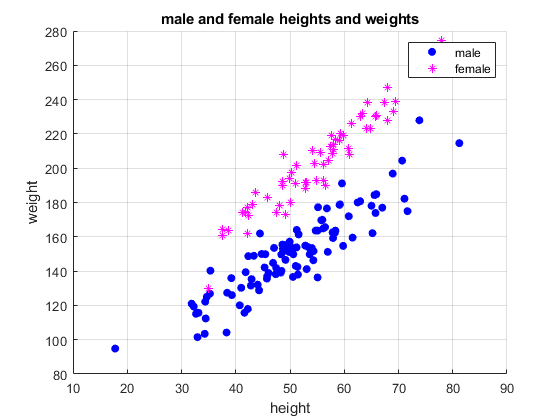

% Visualise the generated data
figure;
hold on;
grid;

scatter(heightM, weightM, 'bo', 'filled');
scatter(heightF, weightF, 'm*');
xlabel('height');
ylabel('weight');
legend('male', 'female');
title('male and female heights and weights');

% Create two classes: M, F
classM = [heightM; weightM];
classF = [heightF; weightF];

% Prepare a grid of points to evaluate the model
ax = axis;
xVals = linspace(ax(1), ax(2), 200);
yVals = linspace(ax(3), ax(4), 200);

[xx, yy] = meshgrid(xVals, yVals);
gridX = [xx(:) yy(:)];

% nearest-prototype classification to predict gender
% for each class -> compute centroid of data points (prototype for a class)
% = the point with coordinates, given by the mean of each input variable;
% to predict the class of an input data point -> choose the nearest
% centroid

% Perform nearest-prototype classifier

% Find centroids of the classes [2x1]
centroidM = mean(classM, 2);
centroidF = mean(classF, 2);

% calculate the distance to centroids of classes M and F
% distToM = sqrt(sum((gridX - centroidMales).^2,2));
distToM = sqrt(sum(bsxfun(@minus, gridX, centroidM').^2,2));
% distaToF = sqrt(sum((gridX - centroidFemales).^2,2));
distToF = sqrt(sum(bsxfun(@minus, gridX, centroidF').^2,2));

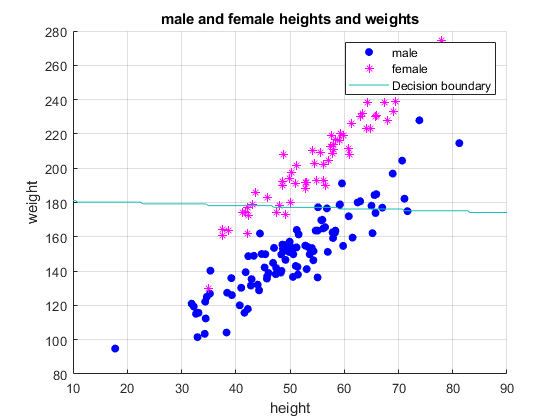

% Create a decision boundary
% 1 for Males, 0 for Females
outputimage = distToM > distToF;
outputimage = reshape(outputimage, [length(xVals) length(yVals)]);
contour(xVals, yVals, outputimage, [.7 .7]);
legend('male', 'female', 'Decision boundary');

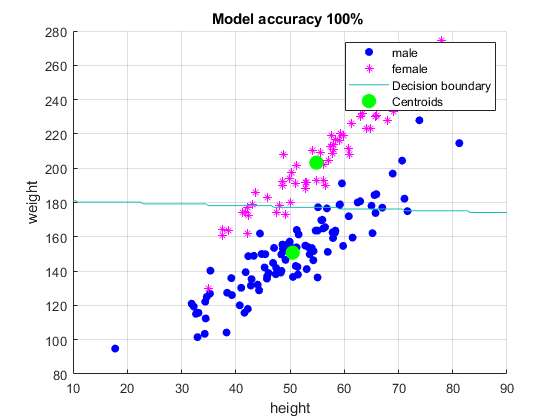

% display centroids
centroids = [centroidM, centroidF];
x = centroids(1, :);
y = centroids(2, :);
plot(x, y, 'go', 'MarkerSize', 10, 'markerfacecolor', 'g');
legend('male', 'female', 'Decision boundary', 'Centroids');
title(sprintf("Model accuracy %.f%% %", 100));

% calculate percentage of correct answers (accuracy)
% prepare full dataset data
X = [heightM' weightM'; ...
    heightF' weightF';];

% 1 for Males, 0 for Females
y = [ones(length(heightM), 1); ...
    zeros(length(heightF), 1)];

% calculate the distance to class M and F
distToM = sqrt(sum(bsxfun(@minus, X, centroidM').^2,2));
distToF = sqrt(sum(bsxfun(@minus, X, centroidF').^2,2));

% suppose that calculated distance to M is lower than to F
pred = distToM < distToF;
% test how exactly the prediction is equal to the sample
pred = pred == y;

acc = sum(pred) / length(pred) * 100;
fprintf('accuracy: %g%%', acc);

accuracy: 83.75%